# Fourier Analysis of the fracture aperture distribution

The objective of this exercise is to implement an idea discussed with Nicola on Friday Feb 25th regarding analyzing fracture specific stiffness. Fracture specific stiffness is defined as "the average applied stressd divided by the average displacement across the fracture interface in excess of the displacement that would occur if the fracture were not present." (Hopkins et al. 1987).

The first thing to do is learn more about Fast-Fourier Transforms (FFT). I will be referring to (Cerna and Harvey, 2000) for guidance in understanding how to use FFT in analysing my data. I want to note that generally speaking, FFT is applied to time-series data i.e. data that change over time. For analysing fractures, we are interested in spacially variable data not time variant, so that will be a distict difference in using FFT.

## Example in Matlab documentation (modified for clarity).

The [fft](matlab:doc('fft')) documentation page has the example shown below. Here, the example has been edited for clarity. To access the original example run the following click [here](matlab:openExample('matlab/FFTOfNoisySignalExample')). 

Define the domain of the calculation

% the sampling frequency must be suffecient to sample the highest
% oscilation frequency. In this case, the max oscilation frequency is
% 12Hz, so sampling frequency of 1000 samples per seconds is sufficient.
samplingFreq        = 1000;                     % Sampling frequency    [samples/sec]             
samplingInterval    = 1/samplingFreq;           % Sampling period       [sec/samples]
tf  = 0.5;                                      % t final               [sec]
t   = 0:samplingInterval:tf-samplingInterval;   % Time vector           [sec]
nSamples = length(t)                            % Length of signal      [samples]

nSamples = 500

Form a signal containing a 50 Hz sinusoid of amplitude 0.7, a 120 Hz sinusoid of amplitude 1, and a DC shift (0 frequency amplitude) of 0.25;

S = 0.25 + 0.7 * sin(2*pi*50*t) + 1 * sin(2*pi*120*t);

ِCorrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2 * randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`.

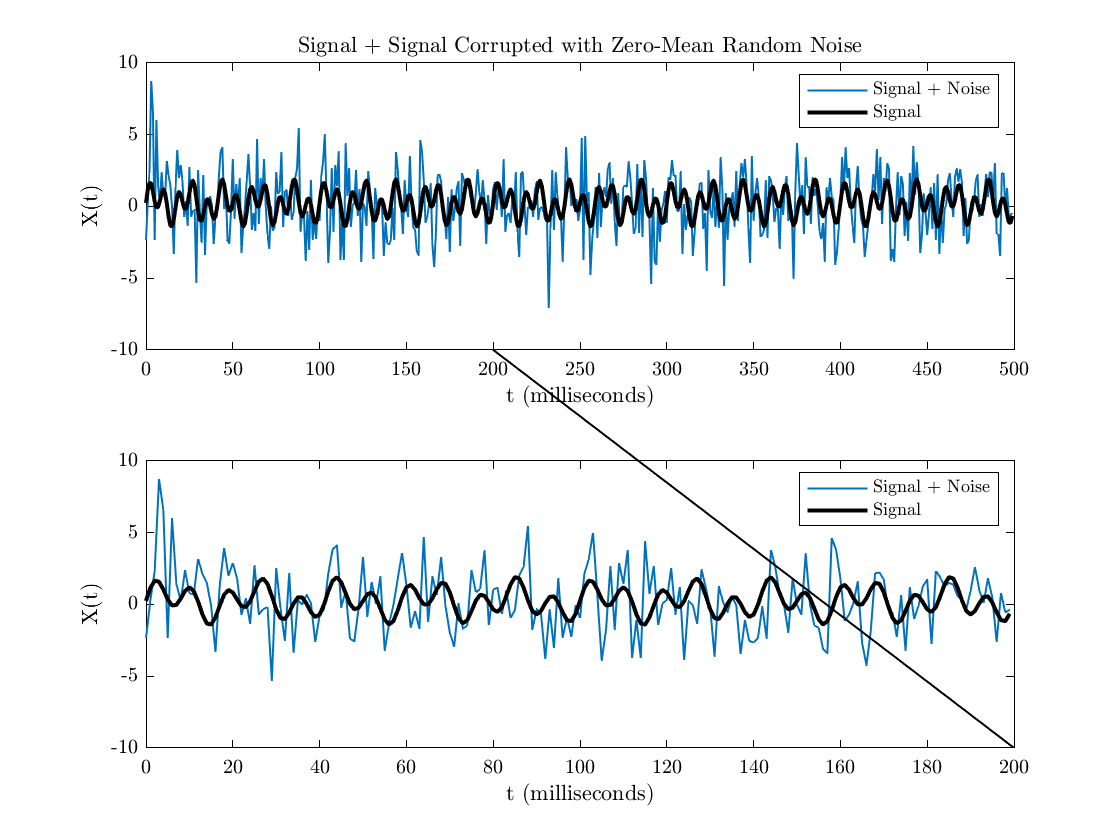

figure
subplot(2,1,1); 
plot(1000*t,X,'DisplayName','Signal + Noise'); hold on;
plot(1000*t,S,'k','DisplayName','Signal','LineWidth',2);
title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax1 = gca;
nsamples = 200;
ax1.XTick = sort(unique([ax1.XTick,nsamples]));

subplot(2,1,2);
plot(1000*t(1:nsamples),X(1:nsamples),'DisplayName','Signal + Noise'); hold on;
plot(1000*t(1:nsamples),S(1:nsamples),'k','DisplayName','Signal','LineWidth',2);
%title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax2 = gca; 
ax2.YLim = ax1.YLim;
% annotations
fig = gcf;

% plot a line between the subplots to relate them to one another
annotation(fig,'line',[ax1.Position(1)+ax1.Position(3)*(nsamples/length(t)) (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);

Compute the Fourier transform of the signal. 

Y = fft(X);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`. 

P2 = abs(Y/nSamples);       % we have to normalize by the signal length
P2(2:end) = 2*P2(2:end);    % we have to multiple all frequency amplitudes by 2 except for the zero frequency amplitude
% extract the single-sided spectrum from P2 before shift the 0 frequency to
% the middle
P1 = P2(1:nSamples/2+1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1, and the double-sided amplitude spectrum P2.` The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

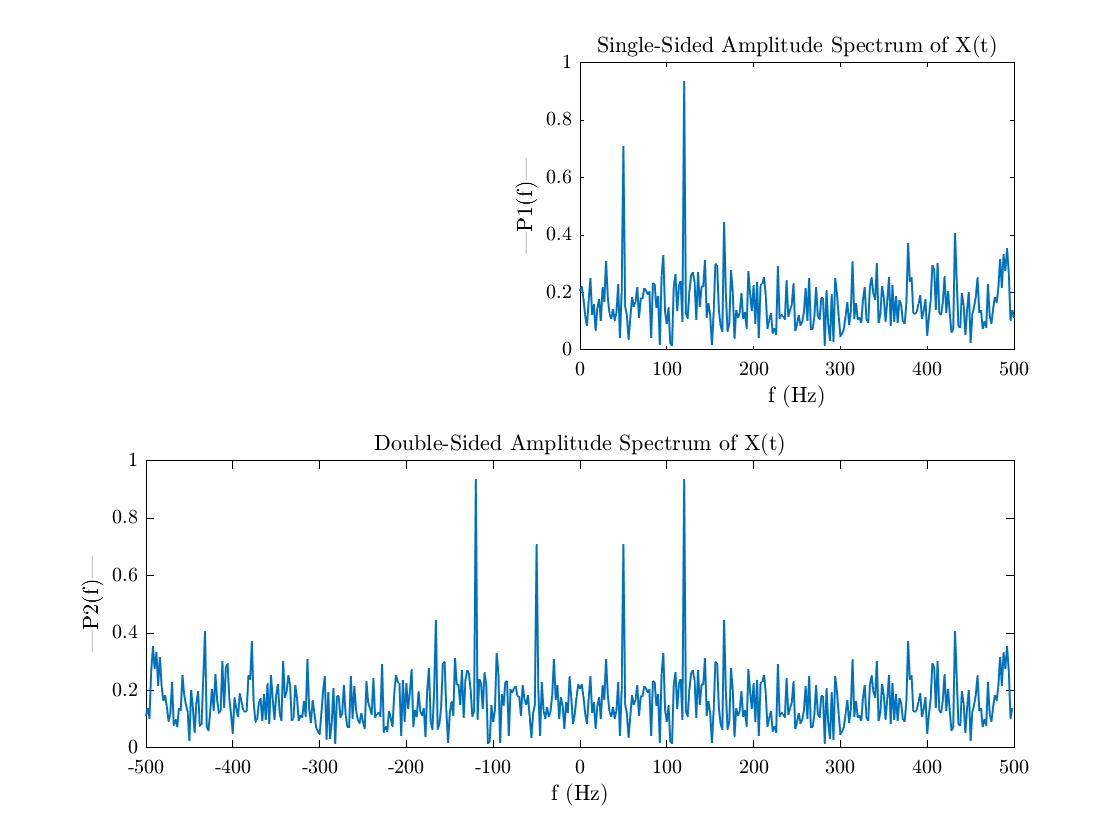

crackY = (0:(nSamples/2)) * (samplingFreq/nSamples);
fshift = (-nSamples/2:nSamples/2-1)*(samplingFreq/nSamples);

P2 = fftshift(P2);

figure
subplot(2,2,2);
plot(crackY,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');
xlim([0 500]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2) 
title('Double-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P2(f)|')
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

Now, zoom in to inspect the 0 frequency element in both plots. I'm doing this to make sure that the determination of the edges of `P1` and `P2` is correct.

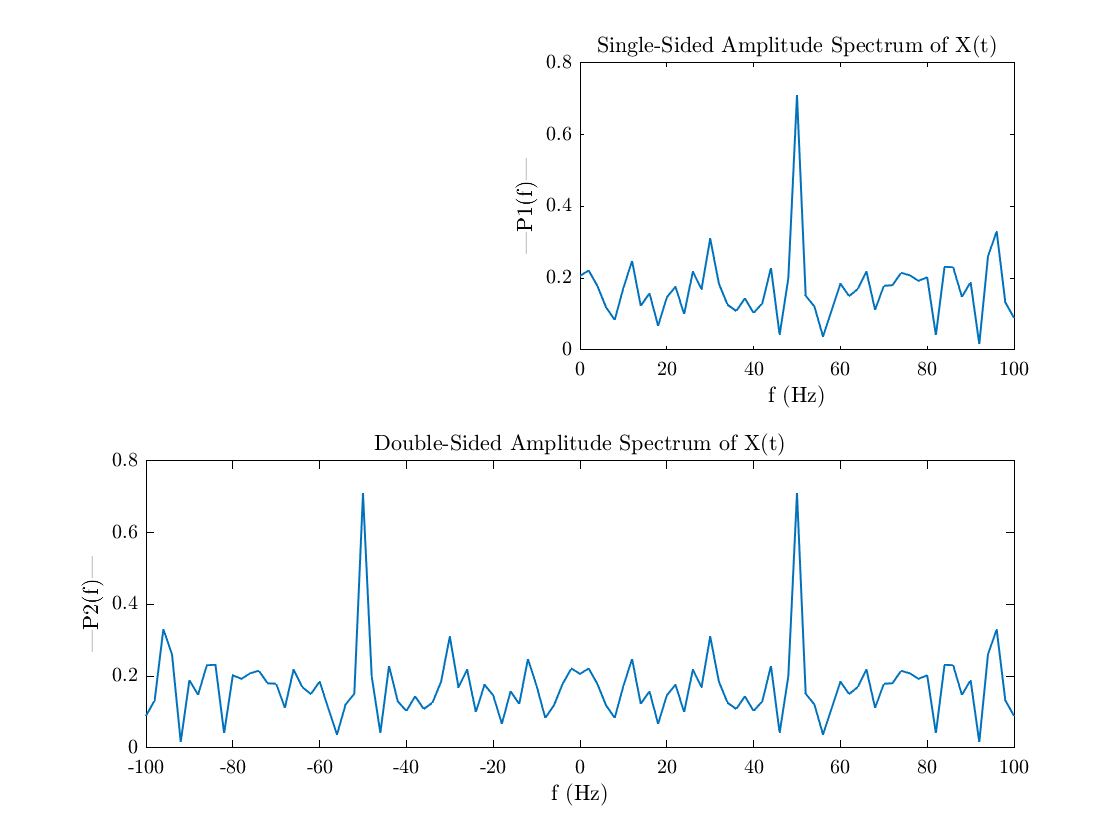

horizontalLim = 100;

figure
subplot(2,2,2);
plot(crackY,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');
xlim([0 horizontalLim]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2) ;
title('Double-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P2(f)|');
xlim([-horizontalLim horizontalLim]);
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

*Copyright 2012 The MathWorks, Inc.*

## Desconstructing the Matlab example for better understanding

The following [link](https://medium.com/analytics-vidhya/breaking-down-confusions-over-fast-fourier-transform-fft-1561a029b1ab) is useful in guiding through applyig `fft` 

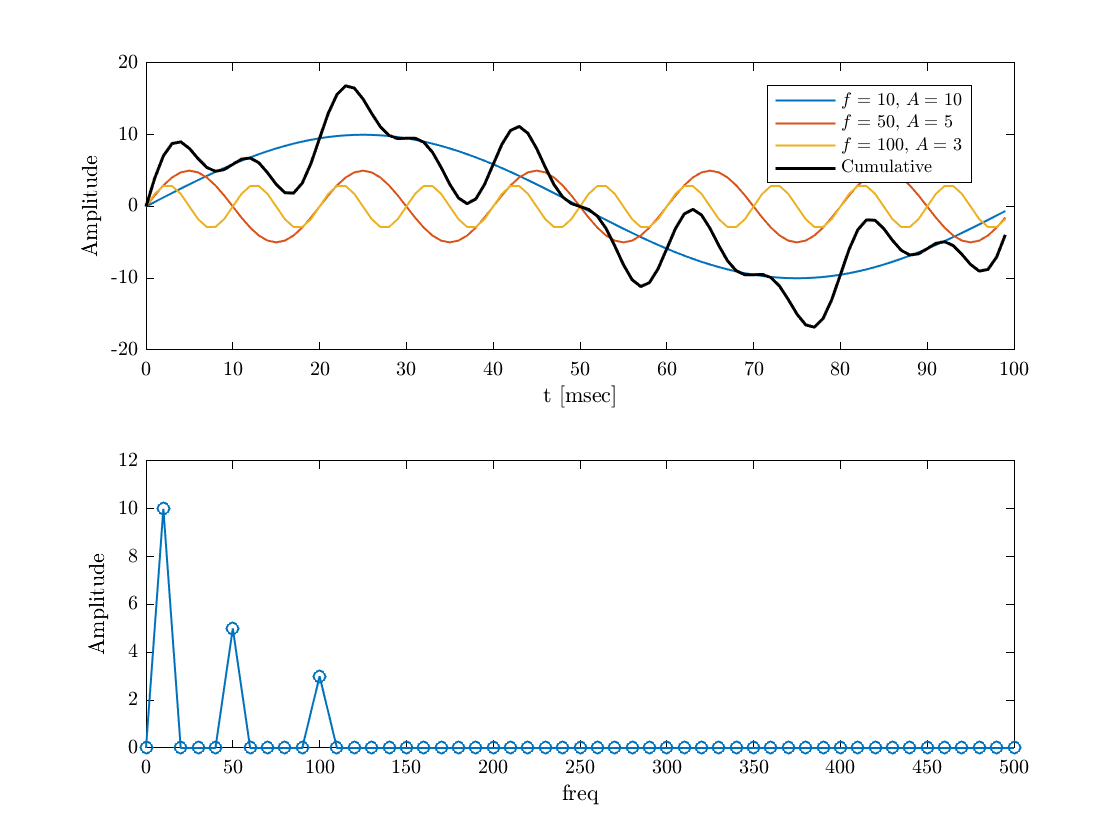

% consider a time series signal that is purely sinosoidal
freq = [10, 50, 100];
amp  = [10, 5, 3];
samplingFreq = 10*max(freq);         % sampling frequencye [sample/time]
samplingInterval = 1/samplingFreq;
tf = 0.1; 
t = 0:samplingInterval:tf-samplingInterval;

y = @(t,f,A) A*sin(2*pi*f*t);

dc = 0; 
x = zeros(size(t));
for i = 1:length(freq)
    x = x + y(t,freq(i),amp(i));
end
% 0 freq (dc) shift
x = x + dc; 

figure
subplot(2,1,1);

for i = 1:length(freq)
    plot(1000*t,y(t,freq(i),amp(i)),'DisplayName',['$f =\ $',num2str(freq(i)), ', $A =\ $',num2str(amp(i))]); hold on;
end

plot(1000*t,x,'-k','DisplayName','Cumulative','LineWidth',1.5); hold on
xlabel('t [msec]');
ylabel('Amplitude');
legend('Location','best');

Y = fft(x);
nSamples = length(t);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
P2 = abs(Y/nSamples);

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
P1 = P2(1:floor(nSamples/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
P1(2:end) = 2*P1(2:end);
 
% to find the x-axis, we need to do the following. I need to study this
% further to better understand it.
freqFFT = (0:1:fix(nSamples/2))*(samplingFreq/nSamples);

subplot(2,1,2);
plot(freqFFT,P1,'-o')
%xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

## Performing the same analysis as the section above using helper functions

% consider a time series signal that is purely sinosoidal
freq = [10, 50, 100];
amp  = [10, 5, 3];
samplingFreq = 10*max(freq);         % sampling frequencye [sample/time]
samplingInterval = 1/samplingFreq;
tf = 0.1; 
t = 0:samplingInterval:tf-samplingInterval;

y = @(t,f,A) A*sin(2*pi*f*t);

dc = 0; 
x = zeros(size(t));
for i = 1:length(freq)
    x = x + y(t,freq(i),amp(i));
end
% 0 freq (dc) shift
x = x + dc; 

figure
subplot(2,1,1);

for i = 1:length(freq)
    plot(1000*t,y(t,freq(i),amp(i)),'DisplayName',['$f =\ $',num2str(freq(i)), ', $A =\ $',num2str(amp(i))]); hold on;
end

plot(1000*t,x,'-k','DisplayName','Cumulative','LineWidth',1.5); hold on
xlabel('t [msec]');
ylabel('Amplitude');
legend('Location','best');

result = myfft(x, samplingFreq);

subplot(2,1,2);
plot(result.freq, result.P1,'-o')
%xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

# 2D FFT

Here we try to generate a 2D fft and see how it looks. Starting by defining an image resolution of `33.3 um, this resolution defines the sampling frequency in our image first then apply the analysis. `

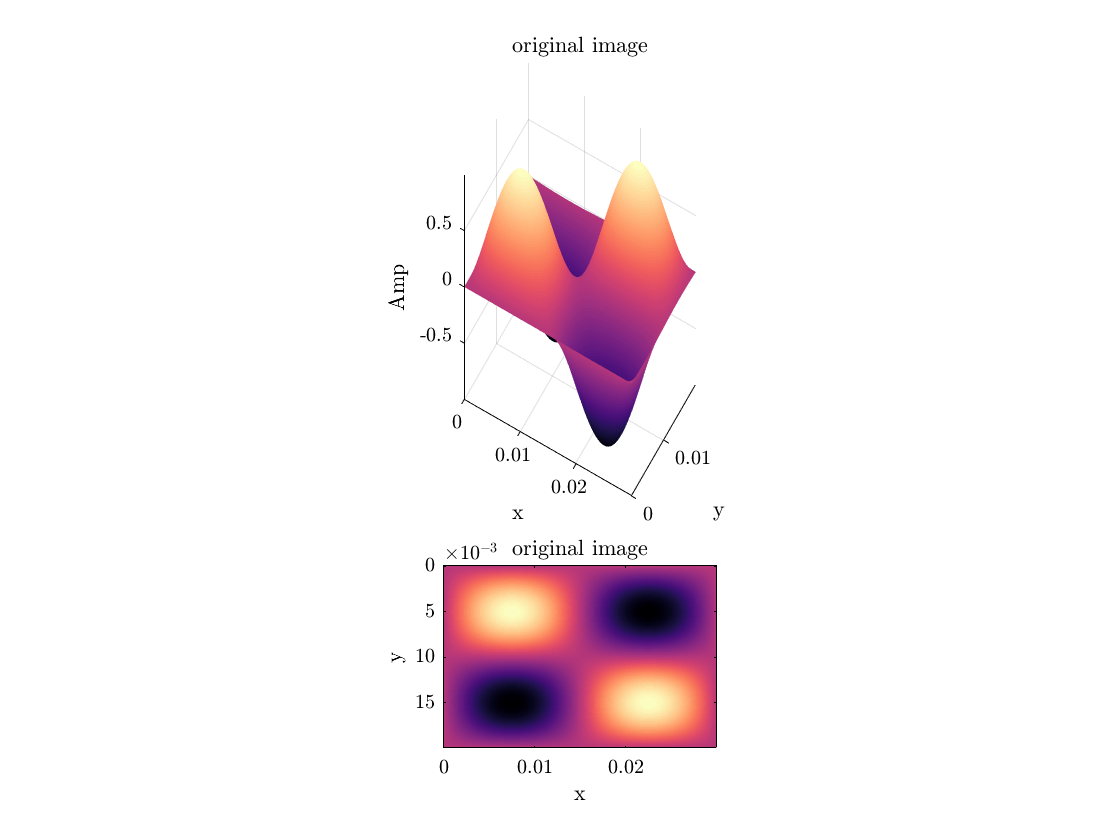

umpermm = 1e3;                  % [micrometer / milimeter]
crackDx = 33.3 *1e-6;                % [m]
samplingFreqX = 1/crackDx;           % [sample/m]
dy = crackDx;                        % [m]
samplingFreqY = 1/dy;           % [sample/m]
xmax = 30 * 1e-3;               % [m]
ymax = 20 * 1e-3;               % [m]

% define the span of the image
X = 0:crackDx:xmax-crackDx;
nSampleX = length(X);

Y = 0:dy:ymax-dy;
nSampleY = length(Y);

[x,y] = meshgrid(X,Y);
originalSize = size(x);

% define the rotation of the waves with respect to the z-axis (deg is the
% degree of rotation using the right-hand-rule where the thumb is aligned
% with the z-axis)
deg = 0;
theta = 2*pi/180 * deg; 
B = [cos(theta)  -sin(theta);
     sin(theta) cos(theta)];

tmp = B*[x(:)';y(:)'];

x = reshape(tmp(1,:),originalSize);
y = reshape(tmp(2,:),originalSize);

% defining the spatial frequencies of the image sinosoids
nCyclesX = 1;
lambdaX = xmax / (nCyclesX);            % [m] the wavelength in the x-direction
freqX = 1/lambdaX;

nCyclesY = 1;
lambdaY = ymax / (nCyclesY);
freqY = 1/lambdaY;

% defining the amplitude and the zero-frequency shift
A = 1;
A0 = 0; 

% generating the image
z = A0 + A .* sin(2*pi*x*freqX) .* sin(2*pi*y*freqY); 

% plotting the image
figure
subplot(3,2,1:4);
surf(X,Y,z);
shading interp
axis image
view([30 89.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');
subplot(3,2,[5,6])
imagesc(X,Y,z);
%shading interp
axis image
%view([0.60 90.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');

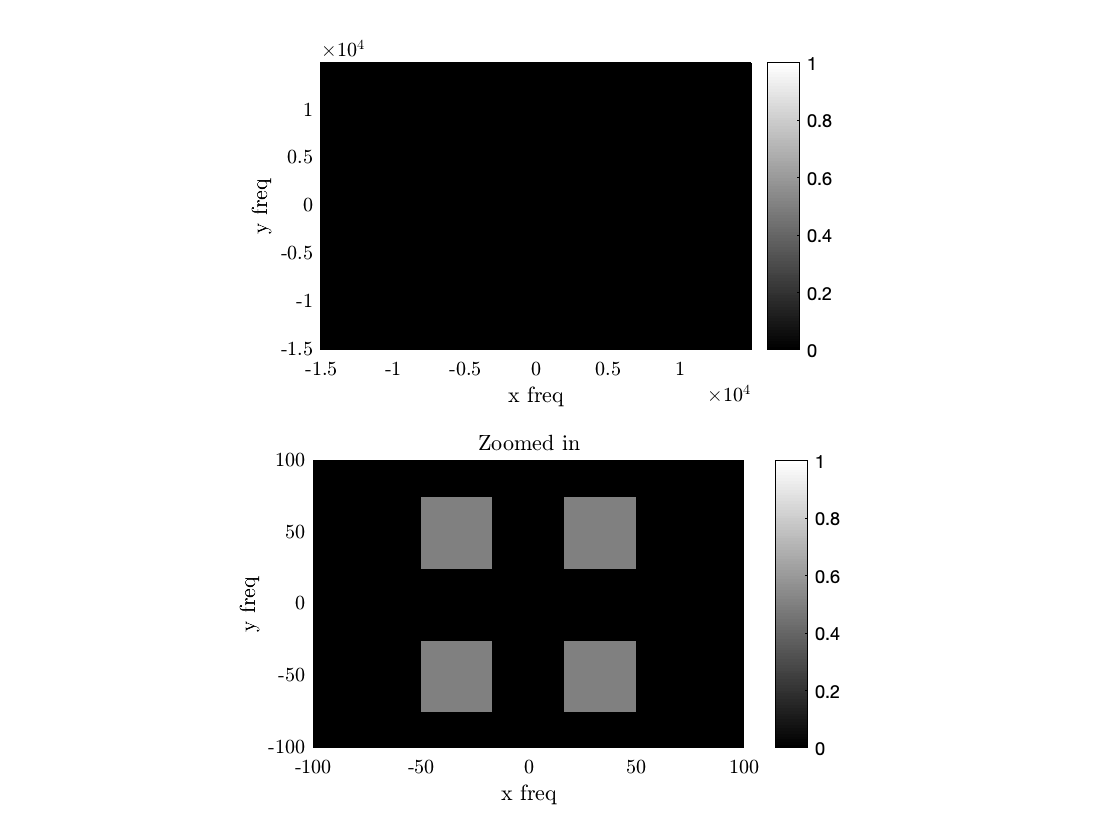


% calculating the fft
% zfft = fft2(z,2^nextpow2(length(Y)),2^nextpow2(length(X)));
zfft = fft2(z);
clear P2
P2 = abs(zfft*(1/nSampleX)*(1/nSampleY));

% extract the DC componenet (0-freq amplitude)
dc = P2(1,1);

% multiply everything by 2. Maybe this needs to be multiplied by 2^2 since
% it is a 2d image??
P2 = 2 * P2;

% reassign the DC componenet
P2(1,1) = dc;

% shift the DC component to the center of the image
P2centered = fftshift(P2); 

% determing the x and y axis in the frequency domain
fshiftX = (-nSampleX/2:nSampleX/2-1)*(samplingFreqX/nSampleX);
fshiftY = (-nSampleY/2:nSampleY/2-1)*(samplingFreqY/nSampleY);

% plotting the amplitudes in the frequency domain
figure
subplot(2,1,1)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax1 = gca;
ax1.CLim = [0 A]; colorbar
ax1.YDir = 'normal';
%axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
%xlim([-2 2]);
%xlim(freqX*[-2 2]);
%ylim(0.1*[-1 1]);
ax1.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

% zoomed in version
subplot(2,1,2)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax2 = gca;
ax2.CLim = [0 A]; colorbar
ax2.YDir = 'normal';
%axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
title('Zoomed in');
xlim(max([freqX freqY])*[-2 2]);
ylim(max([freqX freqY])*[-2 2]);
ax2.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

# Applying FFT on a synthetic crack image

Considering the model of a tappered crack as shown in *Mavko and Nur (1978).*

### *Generating a synthetic image with a single fracture*

#### *Starting with the 1D profiles plotted twice, once with a positive sign, and once with a negative sign*

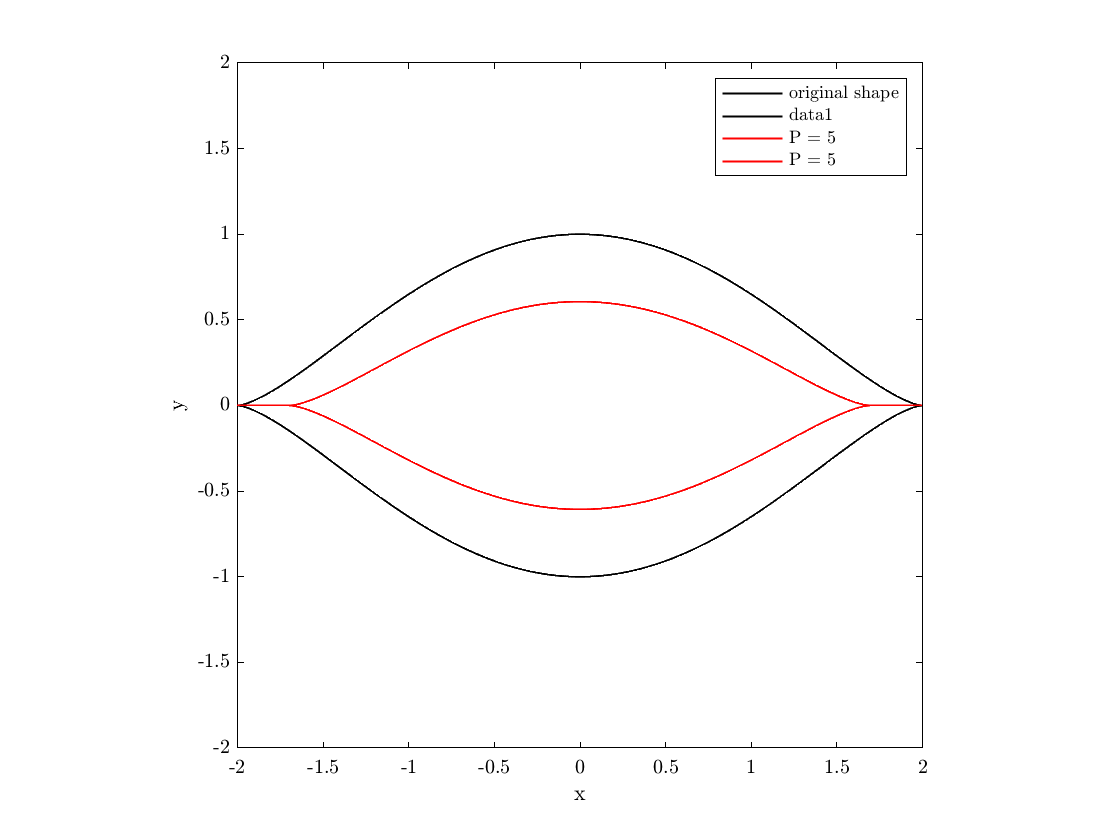

clear dx dy X Y x y;

% crack original properties
c0 = 2;      % half crack width
b = .5;      % half crack aperture (not really, it seems like it cracks aperture/4)
x0 = 0;

% matrix material properties. Considering Calcite properteis (The Rock Physics
% Handbook table A.4.1 in the appendix)
K = 76.8;
mu = 32.0;
nu = 0.32;
E = 2*mu*(1+nu);     % see table 2.2.1 page 23 on The Rock Physics Handbook

% looking at a 1D profile
nsamples = 1000;
crackX = linspace(-c0+x0,c0+x0,nsamples);
crackDx = crackX(2)-crackX(1); 

crackY = @(x,x0,b,c) 2*b*(1-((x-x0)./c).^2).^(3/2);

crackYPlus = crackY(crackX,x0,b,c0);
crackYMinus= -crackY(crackX,x0,b,c0);

crackYAll = [crackYPlus, crackYMinus];
crackXAll = repmat(crackX,1,2);

deg = 0;
theta = deg/180*pi;

B = [cos(theta), -sin(theta);
     sin(theta),  cos(theta)];

tmp = B*[crackX; crackYPlus];
tmp2= B*[crackX; crackYMinus];

crackXPlus = tmp(1,:); 
crackYPlus = tmp(2,:); 
crackXMinus= tmp2(1,:);
crackYMinus= tmp2(2,:);

% crack deformation
% the crack as a function of pressure P and the material properties
crackHalfWidthOfP = @(c0,nu,mu,b,P) c0*sqrt(1 - ((2*(1-nu)/(3*mu*(b/c0)))*P));
P = 5;
crackDeformedHalfWidth = crackHalfWidthOfP(c0,nu,mu,b,P);

crackDeformedX = linspace(-c0+x0,c0+x0,nsamples);
crackDeformedDx = crackDeformedX(2)-crackDeformedX(1); 
crackDeformationY = @(c0,c,b,x) 2*b*(c./c0).^3 * (1 - (x./c).^2).^(3/2);

crackDeformedY = crackDeformationY(c0,crackDeformedHalfWidth,b,crackDeformedX);

figure
l1 = plot(real(crackXPlus), real(crackYPlus),'k','DisplayName','original shape'); hold on;
l2 = plot(real(crackXMinus), real(crackYMinus),'k');

l3 = plot(real(crackDeformedX), real(crackDeformedY),'r','DisplayName',['P = ',num2str(P)]);
l4 = plot(real(crackDeformedX), -real(crackDeformedY),'r','DisplayName',['P = ',num2str(P)]);

legend
xlabel('x');
ylabel('y');
axis equal
xlim([-c0 c0]);
ylim([-c0 c0]);

#### Generating a 2D binary image of the fracture

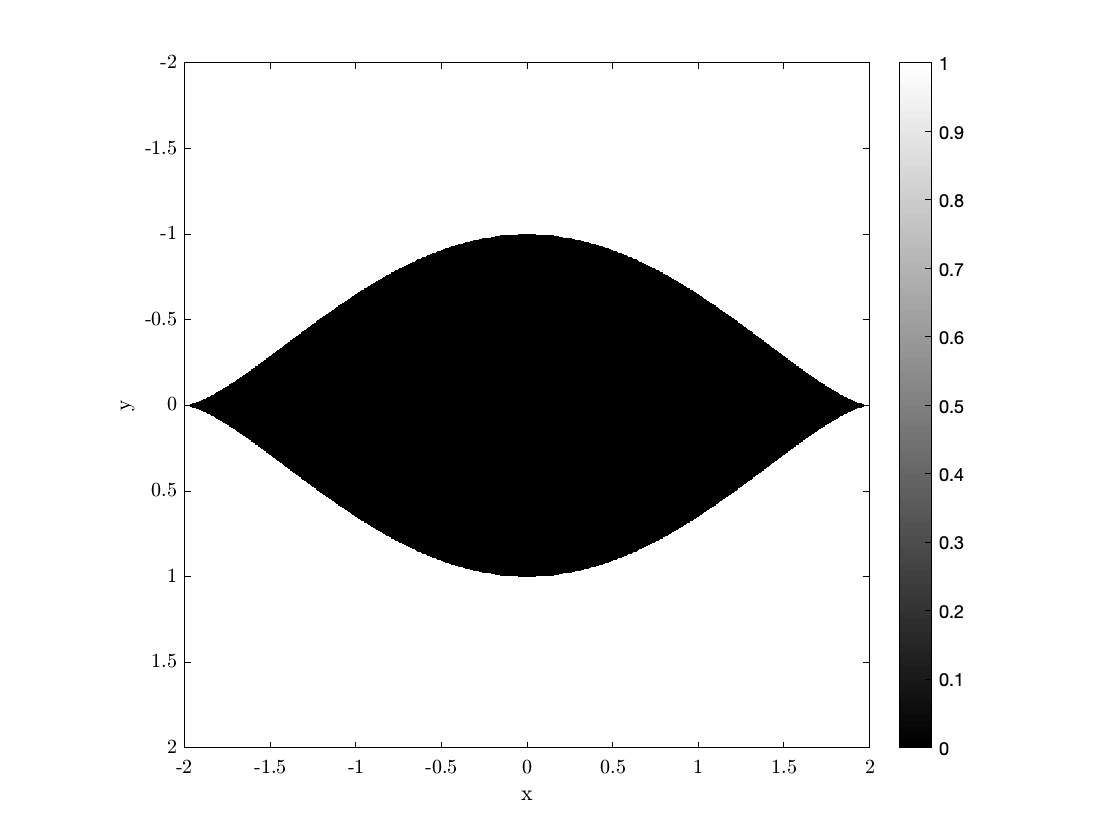

ax = gca;
X = ax.XLim(1):crackDx:ax.XLim(2);
Y = ax.YLim(1):crackDx:ax.YLim(2); 
[xx, yy] = meshgrid(X,Y);
originalSize = size(xx);
tmp = B * [xx(:)';yy(:)'];
xx = tmp(1,:);
xx = reshape(xx,originalSize);
yy = tmp(2,:);
yy = reshape(yy,originalSize); 

crackBinary = ~and((yy - real(crackY(xx,x0,b,c0))) < 0,(yy + real(crackY(xx,x0,b,c0))) > 0);

figure
imagesc(X,Y,crackBinary);
xlabel('x');
ylabel('y');
colorbar
colormap gray
axis image
xlim([-c0 c0]);
ylim([-c0 c0]);

### 1D FFT on the fracture aperture profile

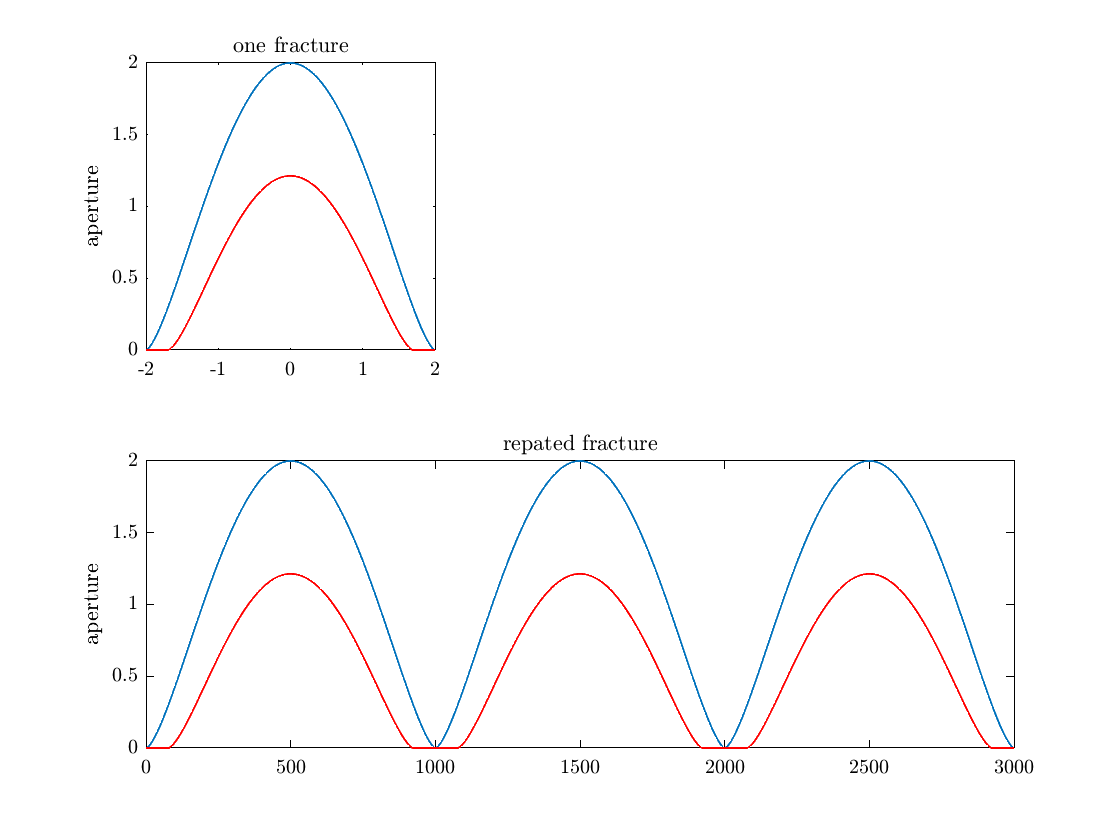


nreplicates = 3;

aperture = crackYPlus-crackYMinus;
apertureDef = real(2*crackDeformedY); % this whill not work when rotating the crack

figure;
subplot(2,nreplicates,1);
plot(crackX, aperture); hold on;
plot(crackDeformedX,apertureDef,'r');
title('one fracture');
ylabel('aperture');
ax1 = gca;
crackRepeatedAperture = repmat(aperture,1,nreplicates);
crackDeformedRepatedAperture = repmat(apertureDef,1,nreplicates);
subplot(2,nreplicates,nreplicates+1:2*nreplicates);
plot(crackRepeatedAperture); hold on;
plot(crackDeformedRepatedAperture,'r');

title('repated fracture');
ylabel('aperture');
ax2 = gca;
ax1.Position(3) = ax2.Position(3)/nreplicates;

Now we look at the FFT of the aperture

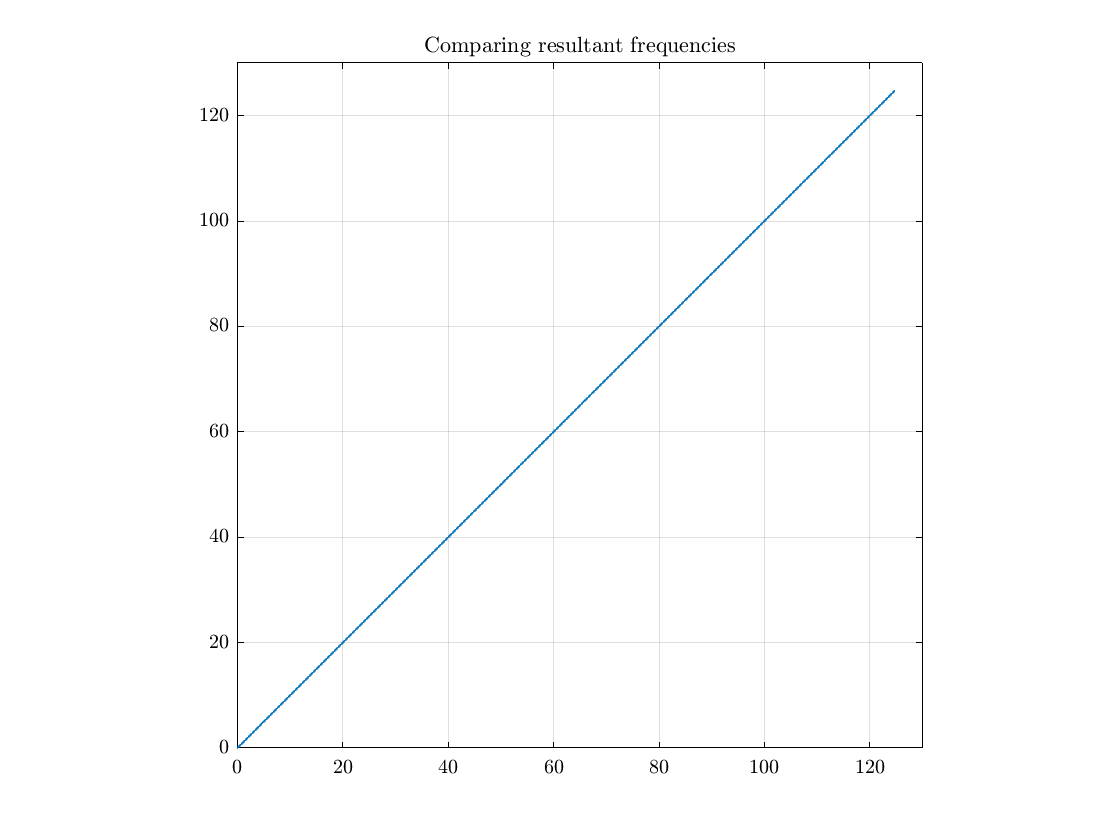

crackFFTResult = myfft(crackRepeatedAperture,1/crackDx); 
crackDeformedFFTResult = myfft(crackDeformedRepatedAperture, 1/crackDeformedDx);
figure
plot(crackFFTResult.freq, crackDeformedFFTResult.freq);
title('Comparing resultant frequencies');   
axis equal; grid on;
xlim([0 130]);
ylim([0 130]);

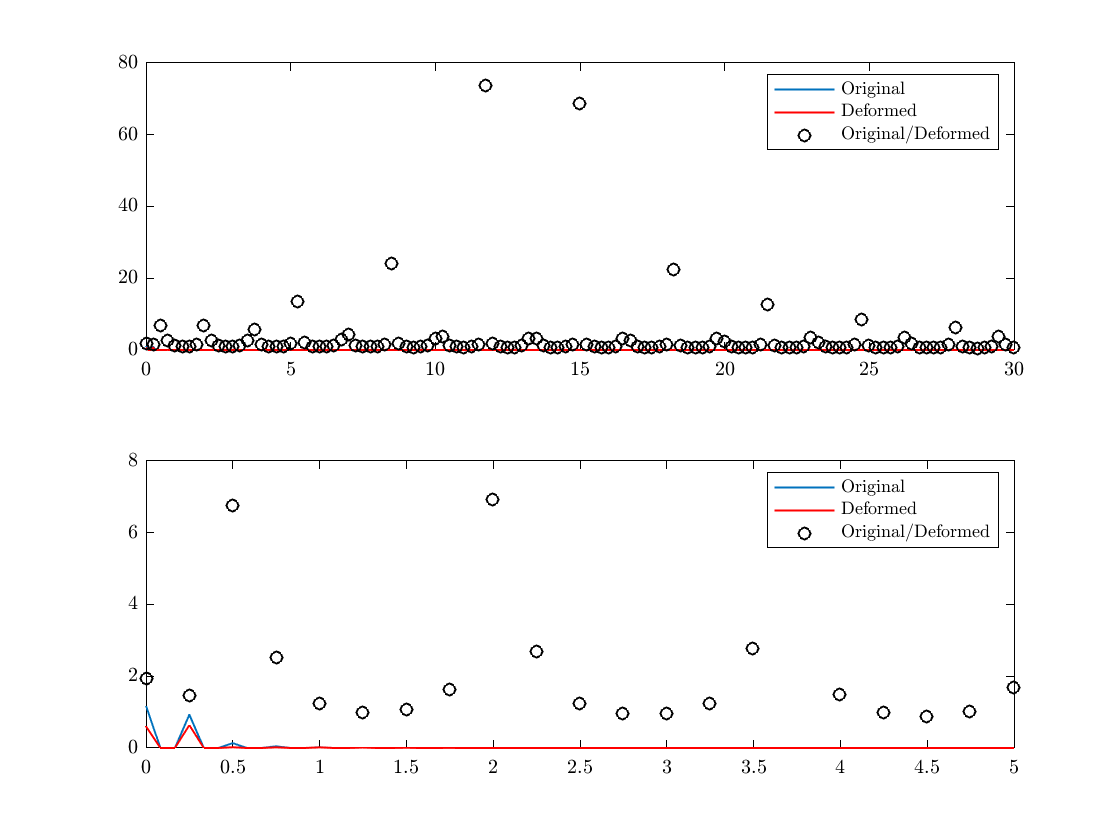

figure
subplot(2,1,1);
plot(crackFFTResult.freq, crackFFTResult.P1,'DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.freq, crackDeformedFFTResult.P1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult.freq, (crackFFTResult.P1./crackDeformedFFTResult.P1),'ok','DisplayName','Original/Deformed');

ax = gca;
ax.XLim = [0 30];
legend();
subplot(2,1,2);
plot(crackFFTResult.freq, crackFFTResult.P1,'DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.freq, crackDeformedFFTResult.P1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult.freq, (crackFFTResult.P1./crackDeformedFFTResult.P1),'ok','DisplayName','Original/Deformed');

ax = gca;
ax.XLim = [0 5];
legend();

#### Loading an actual image to determine the proper values of the fracture and the matrix binary image

sevenAFolder = fullfile('..','..','data','Bland','7A_fractured','8bitJPG');
sevenA.original = loadImageSeq(sevenAFolder,'jpg');

loadImageSeq: file extension are properly formatted as jpg
loadImageSeq: loading image sequence from: ../../data/Bland/7A_fractured/8bitJPG
loadImageSeq:....................................................................................................100%
loadImageSeq completed in 22.571546.3 seconds


#### Displaying a slice of the data

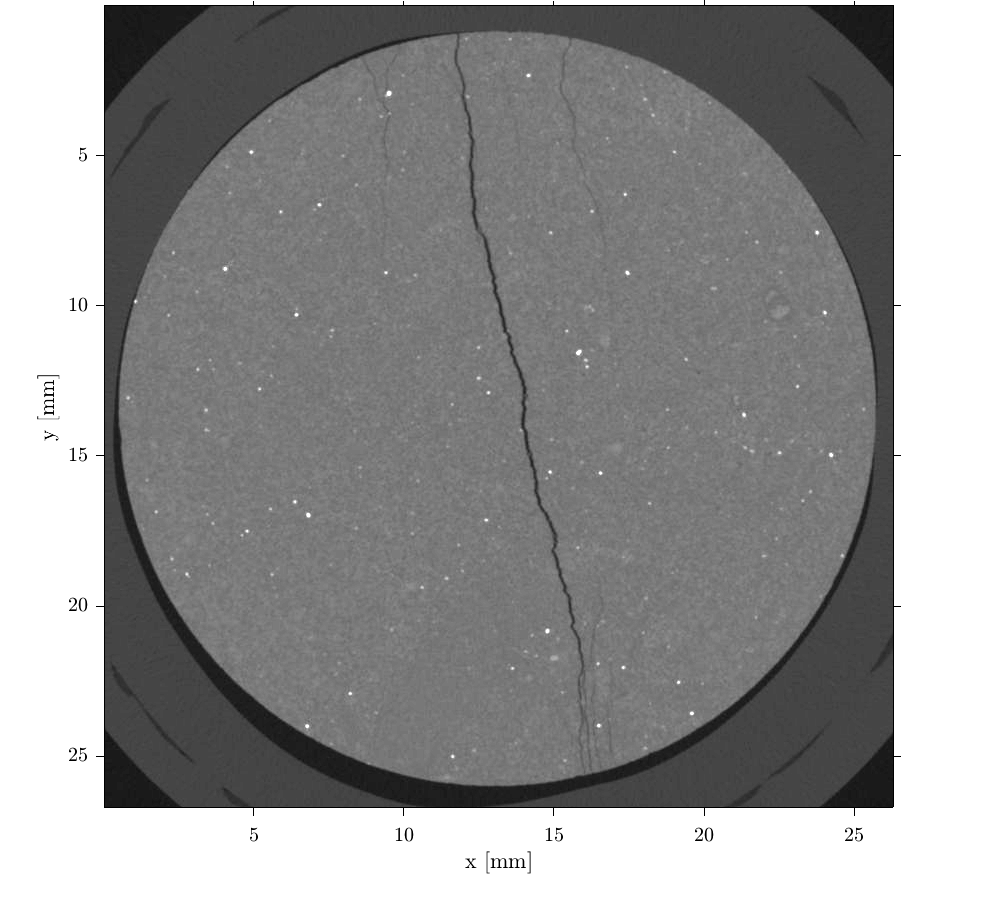

sliceIndex = 800;
image7aOriginal = uint8(sevenA.original.image(:,:,sliceIndex));
image7a = imadjust(image7aOriginal,[0 .35]);
res = 33.3*1e-3; %[mm]
figure
colormap gray
% setting world reference 
worldRef = imref2d(size(image7a),res,res);
imgout = imshow(image7a,worldRef);
axis image
xlabel('x [mm]');
ylabel('y [mm]');
ax = gca;
% ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;

#### In order to use the synthetic model properly, we need to quantify the noise, and  the mean gray values of the matrix and the fracture in the image. I stopped working on this, will come back to it later.

I started working on this, but encountered some issues regarding fitting a Gaussian through a fracture, and I stopped working on it for now

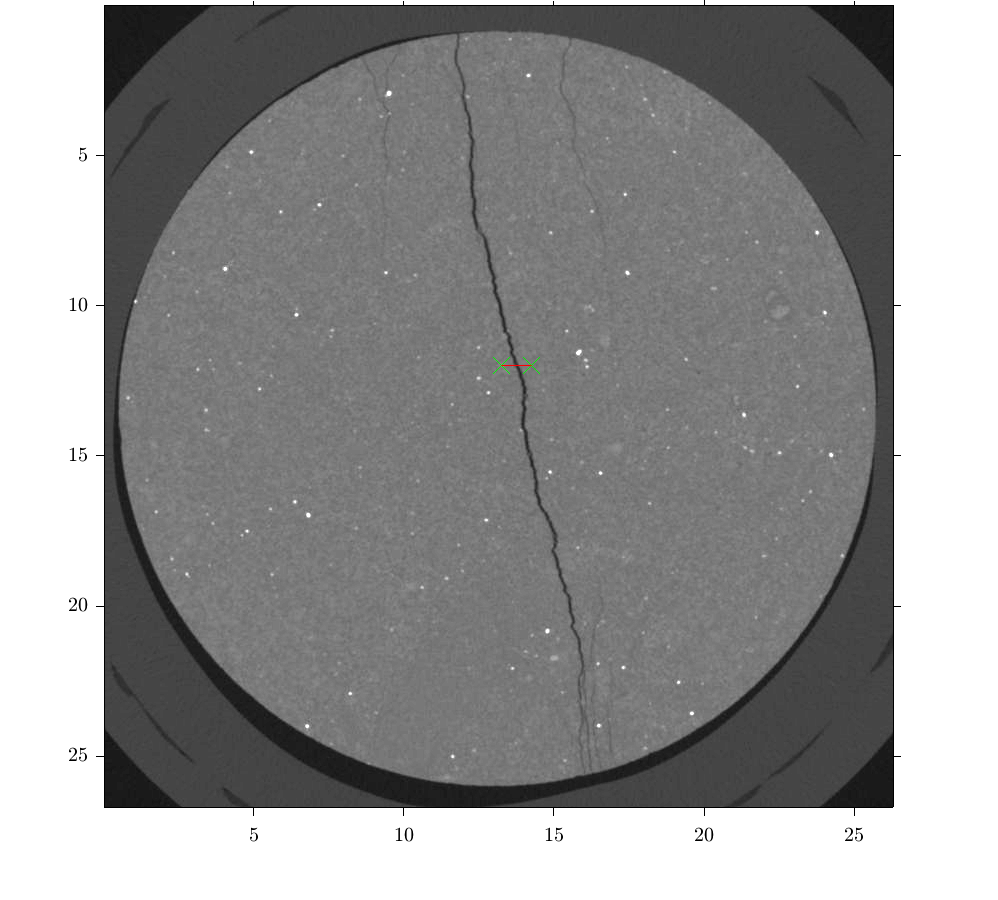

% Determine the profile along which I will show the gray values
lineXWorldCoord = [13.25 14.25];
lineYWorldCoord = [12 12];
[cx,cy,c0,xl,yl] = improfile(worldRef.XWorldLimits,worldRef.YWorldLimits,image7aOriginal,lineXWorldCoord,lineYWorldCoord);
[lineXIndexCoord,lineYIndexCoord] = worldRef.worldToIntrinsic(xl,yl);
aimg = insertMarker(image7a,[lineXIndexCoord lineYIndexCoord],'x','Size',8);
aimg = insertShape(aimg,'Line',[lineXIndexCoord(1), lineYIndexCoord(1), lineXIndexCoord(2), lineYIndexCoord(2)],'Color','r','LineWidth',1);

figure
imshow(aimg, worldRef);
ax = gca;
ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;

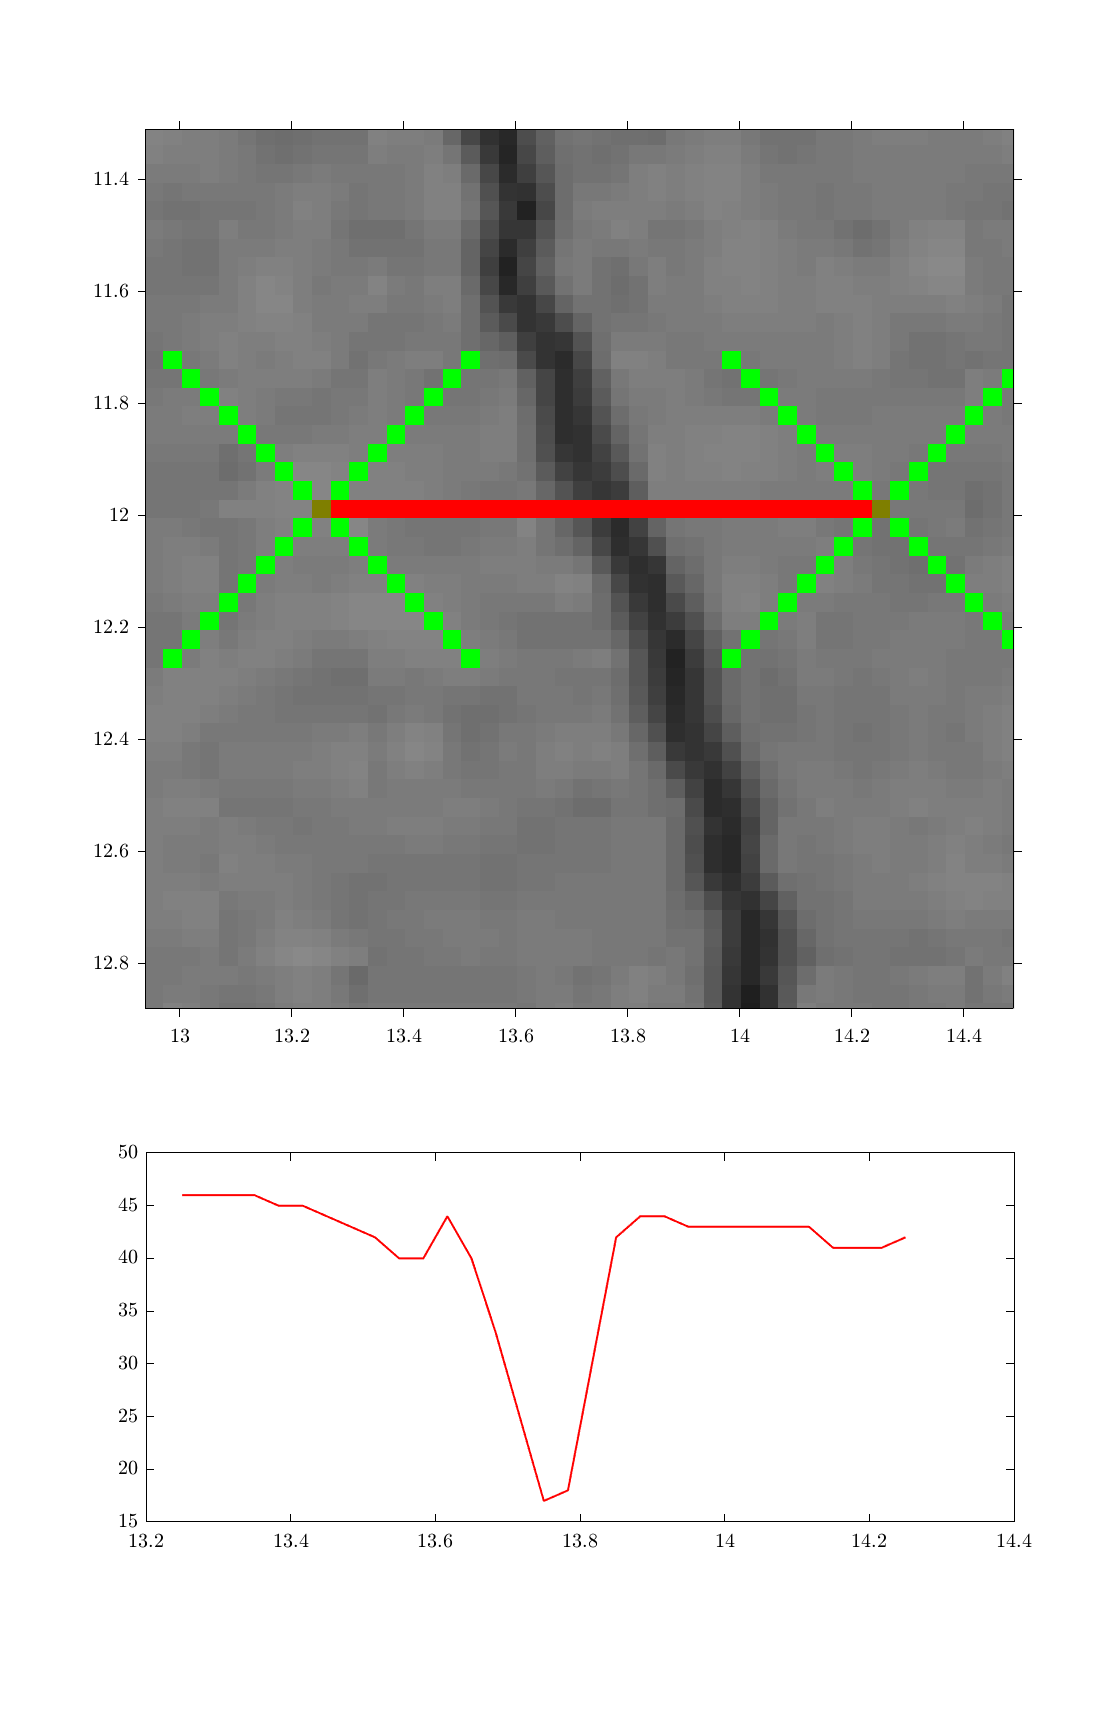

figure('Position',[681 124 560 855]);
subplot(3,2,1:4);
imshow(aimg, worldRef);
ax = gca;
ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;
xlim([12.94 14.49])
ylim([11.31 12.88])

subplot(3,2,5:6);
newcx = cx-cx(1); newcy = cy-cy(1); 
r = sqrt(newcx.^2 + newcy.^2) + lineXWorldCoord(1);
plot(r,c0,'r')

# Side Notes

## Online University Physics book

In an attempt to understand the difference between amplitude and power, I found the following link that explains power very well: [https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.](https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.)

The link is part of an online text book on university physics.

# References

Cerna, M., and A. F. Harvey, 2000, The Fundamentals of FFT-Based Signal Analysis and Measurement: Application Note 041, National Instruments.  

Chuan-Zheng Lee (2017). *Signals and the frequency domain*. (pdf). Available from: <https://web.stanford.edu/class/archive/engr/engr40m.1178/slides/signals.pdf>. [Accessed 02/28/2022 ].

Hopkins, D. L., N. G. W. Cook, and L. R. Myer, 1987, Fracture Stiffness And Aperture As A Function Of Applied Stress And Contact Geometry: , ARMA-87-0673.

Mavko, G. M., and A. Nur, 1978, The effect of nonelliptical cracks on the compressibility of rocks: Journal of Geophysical Research, **83**, 4459.

# Helper functions

function result = myfft(input, samplingFrequency)
result.fft = fft(input);
nSamples = length(input);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
result.P2 = abs(result.fft/nSamples);

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
result.P1 = result.P2(1:floor(nSamples/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
result.P1(2:end) = 2*result.P1(2:end);

% to find the x-axis, we need to do the following. I need to study this
% further to better understand it.
result.freq = (0:1:fix(nSamples/2))*(samplingFrequency/nSamples);
end